# Capacitors: charge/discharge

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

In this script, we will explore the charge and discharge of capacitors and how they can store energy.

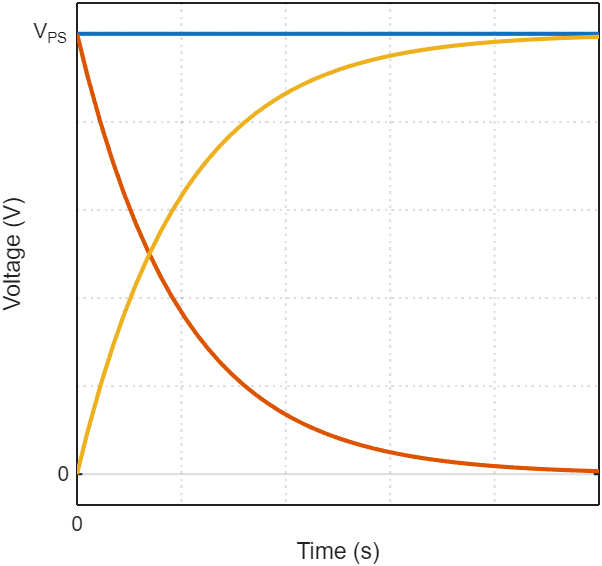

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB. Part of this script include Simscape simulations, no prior knowledge is assumed here, but you might want to consider taking [Simscape Onramp](https://matlabacademy.mathworks.com/details/simscape-onramp/simscape) as well.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Charging a Capacitor

In the previous section, we have seen how an accumulation of charge on the plates of the capacitor would result in the creation of an electrical potential differential between the plates:

$V_C = \frac{Q}{A\varepsilon_0}d$.

Let's go back to our simulation. At the initial time, the electrical circuit looked like this:

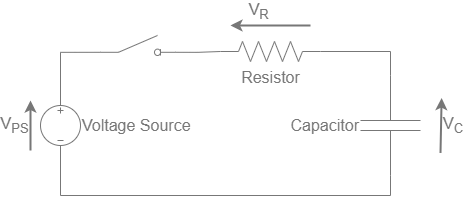

The capacitor is fully discharged, meaning its plate's charge density is $\sigma = 0\ C/\text{m}^2$.

**We now close the circuit:**

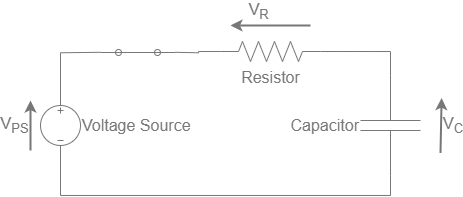

We can apply Kirchhoff's voltage law so that:


$$V_{PS} = V_{R}+V_{C} \qquad (\clubsuit)$$


With:

- $V_{PS}$ the power supply voltage

- $V_R$ the voltage drop across the resistor

- $V_C$ the voltage drop across the capacitor

 **Exercise 6. **Immediately after closing the circuit, what are the values of $V_R$ and $V_C$?

- You can enter `V_PS `for the power supply voltage.

CheckExercise6("V_PS"...
    ,"0");

Good job! You got the voltages right.


 

function CheckExercise6(V_R,V_C)
    V_PS = sym("V_PS");
    V_R = str2sym(V_R);
    V_C = str2sym(V_C);
    
    if V_R == V_PS
    elseif V_R == 0
         warning("The resistor's voltage would not be zero right after the switch closes.")
    else
        warning("The resistor's voltage would be equal to the power supply's voltage right after the switch closes.")
    end
    
    if V_C == V_PS
        warning("The capacitor's voltage would not be equal to the power supply's voltage right after the switch closes.")
    elseif V_C == 0
    else
        warning("The capacitor's voltage would be zero right after the switch closes.")
    end
    
    if V_R == V_PS & V_C == 0
        disp("Good job! You got the voltages right.")
    end
end

We can also compute the current going through the loop with Ohm's Law:


$$i=\frac{V_R}{R}$$


The current applied to the circuit is what will bring charges to the plates of the capacitor and, therefore, create a potential difference between the plates. Recall that

$i = \frac{dQ}{dt}$, 

using $Q = CV_c$, this becomes

$i = C\frac{dV_C}{dt}$.

Therefore, 


$$C\frac{dV_C}{dt} = \frac{V_R}{R}. \qquad (\spadesuit)$$


 **Exercise 7. **Combine $(\clubsuit)$ and $(\spadesuit)$ to form the differential equation governing the capacitor charge as a function of $V_C$, $V_{PS}$, $R$ and $C$.

CheckExercise7("diff(V_C)","(V_PS-V_C)/(C*R)");

Good job! You defined the differential equation correctly.


$$DifferentialEquation(t) = \frac{\partial }{\partial t}V_{C}\left(t\right)=\frac{V_{\mathrm{PS}}-V_{C}\left(t\right)}{C\,R}$$

$$InitialCondition = V_{C}\left(0\right)=0$$

$$V\_C = V_{\mathrm{PS}}-V_{\mathrm{PS}}\,{\mathrm{e}}^{-\frac{t}{C\,R}}$$

 

function CheckExercise7(LeftHandSide,RightHandSide)

    syms C V_C(t) V_PS R
    [~,LeftHandSide] = evalc(LeftHandSide);
    [~,RightHandSide] = evalc(RightHandSide);
    
    Answer = isolate(LeftHandSide == RightHandSide,diff(V_C(t), t));
    Solution = diff(V_C(t),t) == (V_PS-V_C)/(R*C);

    if isAlways(rhs(Answer)==rhs(Solution),Unknown="false")
        disp("Good job! You defined the differential equation correctly.")
        DifferentialEquation = LeftHandSide == RightHandSide
        InitialCondition = V_C(0) == 0
        V_C = dsolve(DifferentialEquation,InitialCondition)
    else
        warning("Wrong, follow the following step this time:"+newline+...
            "          - Isolate the resistor voltage from (♣)"+newline+...
            "          - Substitute it into (♠)")
    end
end

  **Try. **Visualize the voltage drop across various components over time.

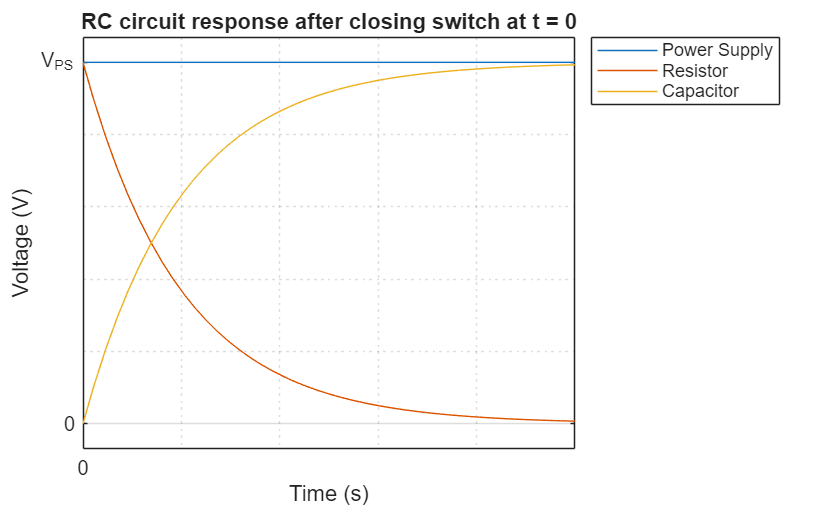

PlotCapacitorCharge({true; true; true});

 

function PlotCapacitorCharge(Show)
    syms C V_C(t) V_PS R
    diffEq = C*diff(V_C) == (V_PS-V_C) / R;
    cond = V_C(0) == 0;
    V_C = dsolve(diffEq,cond);
    p(1) = fplot(5,[0 5],DisplayName="Power Supply");
    hold on
    p(2) = fplot(5-subs(V_C,[V_PS R C],[5 1000000 1e-6]),[0 5],DisplayName = "Resistor");
    p(3) = fplot(subs(V_C,[V_PS R C],[5 1000000 1e-6]),[0 5],DisplayName="Capacitor");
    hold off
    xlabel("Time (s)")
    ylabel("Voltage (V)")
    legend(Location="bestoutside")
    ylim("padded")
    grid on
    ax = gca;
    ax.XTick = 0;
    ax.YTick = [0 5];
    ax.YTickLabel = {'0','V_{PS}'};
    ax.XMinorGrid = 'on';
    ax.YMinorGrid = 'on';
    set(p,{'Visible'},Show);
    title("RC circuit response after closing switch at t = 0")
end

**Back to our simulation**

Now that we know how capacitors function and how they react when connected to a power supply, we still have to explain why they appear to behave as both conductors and insulators!

That confusion actually comes from how we measure current. We have to connect a multimeter to measure current, and we will have to connect it in series to our circuit so we can measure the current before or after the capacitor but not through the capacitor. Our measured current looks at the charge moving toward the capacitor plates, but there is no charge "jumping" from one plate to the other.

You could visualize capacitor plates as two water tanks, one filling with positive charges and one filling with negative charges on the other side. The accumulation of charge on each plate creates a voltage difference. The charge keeps accumulating until the potential difference between the plates balances the voltage supplied by the power supply.

  **Try.** Animation charge discharge capacitor

 
CapacitorCharge;

function CapacitorCharge()
    % Simulate RC Circuit
    Model = "SimpleRC";
    SimIn = Simulink.SimulationInput(Model);
    SimIn = setBlockParameter(SimIn,"SimpleRC/Signal Editor","ActiveScenario","SimpleCharge");
    SimOut = sim(SimIn);
    
    % Get datapoints:
    TimeSim = SimOut.SimlogSimpleRC.DC_Voltage_Source.i.series.time;
    SwitchState = SimOut.SimlogSimpleRC.Switch_1.vT.series.values;
    Current = -SimOut.SimlogSimpleRC.DC_Voltage_Source.i.series.values;
    % CapacitorVoltage = SimOut.SimlogSimpleRC.Capacitor.v.series.values;
    
    % Interpolate results to create more frames:
    Time = linspace(min(TimeSim),max(TimeSim),150);
    SwitchState = interp1(TimeSim,SwitchState,Time);
    Current = interp1(TimeSim,Current,Time);
    % CapacitorVoltage = interp1(TimeSim,CapacitorVoltage,Time);
    CapacitorCharge = cumsum(Current);
    
    figure
    tl = tiledlayout(2,2);
    
    % Top left
    nexttile(1)
    OpenRC.CData = 1;
    OpenRC.Alpha = 1;
    ClosedRC = OpenRC;
    [OpenRC.CData,~,OpenRC.Alpha] = imread(fullfile("Images","OpenRC.png"));
    [ClosedRC.CData,~,ClosedRC.Alpha] = imread(fullfile("Images","ClosedRC.png"));
    Circuit = imshow(OpenRC.CData);
    
    % Bottom left
    nexttile(3)
    CurrentLine = animatedline;
    axis([0,max(Time),0,max(Current)])
    xlabel("Time")
    ylabel("Current")
    
    % Top right
    nexttile(2);
    f = [1 2 3 4];
    vT = @(eta) [-2 0.8; eta*4-2 0.8; eta*4-2 1.2; -2 1.2];
    vB = @(eta) [-2 -1.2; eta*4-2 -1.2; eta*4-2 -0.8; -2 -0.8];
    patch(Faces=f,Vertices=vT(1),FaceColor='none',SeriesIndex="none")
    patch(Faces=f,Vertices=vB(1),FaceColor='none',SeriesIndex="none")
    pT = patch(Faces=f,Vertices=vT(0),FaceColor='blue',EdgeColor='none');
    pB = patch(Faces=f,Vertices=vB(0),FaceColor='red',EdgeColor='none');
    
    % Bottom right
    nexttile(4)
    ChargeLine = animatedline;
    axis([0,max(Time),0,max(CapacitorCharge)])
    xlabel("Time")
    ylabel("Charge")
    drawnow
    
    % Animate
    for Frame = 1:length(Time)
        addpoints(CurrentLine,Time(Frame),Current(Frame))
        addpoints(ChargeLine,Time(Frame),CapacitorCharge(Frame))
        if SwitchState(Frame)
            Circuit.CData = ClosedRC.CData;
            Circuit.AlphaData = ClosedRC.Alpha;
        else
            Circuit.CData = OpenRC.CData;
            Circuit.AlphaData = OpenRC.Alpha;
        end
        pT.Vertices = vT(CapacitorCharge(Frame)/max(CapacitorCharge));
        pB.Vertices = vB(CapacitorCharge(Frame)/max(CapacitorCharge));
        title(tl,"t = "+Time(Frame));
        drawnow
    end
end

## Discharging a Capacitor

We have been exploring how to charge a capacitor, but you should know that we can also discharge a capacitor.

  ** Try. ** Open the model and change the active scenario in the ** Signal Editor ** block to ** ChargeDischarge **. Run the charge-discharge scenario, then visualize the current (either in MATLAB with the button below or in the Simscape Results Explorer).

 
open_system("SimpleRC")

 
if exist("out","var")
    plot(out.SimlogSimpleRC.Capacitor.i);
    title("Capacitor")
    ylabel("Current (A)")
    xlabel("Time (s)")
    ylim("padded")
    xlim([0 10])
    grid off
else
    warning("Run the simulation in the SimpleRC.slx Simscape model if you want to visualize the results.")
end

You can see that the capacitor is now seeing two spikes of current:

- The positive spike corresponds to the charging of the capacitor. This happens as the first switch is closed and the second switch is open.

- The negative spike corresponds to the discharging of the capacitor. This happens as the first switch is open and the second switch is closed.

**Exercise 8. **During the discharge, the first switch was in the open position and the second switch was in the closed position. What component(s) were connected to the capacitor?

Answer = [false false]; 
 
if Answer(1)
    warning("At this point, the power supply is no longer connected to the capacitor.")
elseif ~Answer(2)
    warning("The resistor is always connected to the capacitor independent of the state of each switch.")
elseif all(Answer == [0 1])
    disp("Good job! The capacitor is only connected to the resistor at this point.")
elseif all(Answer == [0 0])
        warning("Please select an answer.")
end

 **Reflect. **So, where was the energy coming from during the discharge phase?

  **Try.** Check the answer!

 
disp("The capacitor was storing energy that can be delivered back to the resistor.")

The capacitor was storing energy that can be delivered back to the resistor.


disp("The energy stored in the capacitor is:")

The energy stored in the capacitor is:


% syms V_C
displayFormula(["U = 1/2*C*V_C" "" ""; ...
"'with:'" "" "" ; ... 
"'   '" "U" "' is the energy in joules'"; ...
"'   '" "C" "' is the capacitance in farads'"; ...
"'   '" "V_C" "' is the capacitor voltage'"])

$$U=\frac{1}{2}\,C\,V_{C}$$

$$\mathrm{with:}$$

$$U\mathrm{is the energy in joules}$$

$$C\mathrm{is the capacitance in farads}$$

$$V_{C}\mathrm{is the capacitor voltage}$$

## Further Exploration

## Conclusion

In this script, we explored the essential role of capacitors in electrical circuits, focusing on their ability to store and release energy. We've determined an analytical value for the capacitance of a plate capacitor based on its physical factors. Through Simscape simulation, we explored the charge and discharge of the capacitor and illustrated how it stores energy.

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))